load('exp/exp_lognorm/exp_ln_wo_BM.mat');

## Figure 1: prevented loss and the discounted profit of the insurer

transition1_counter = find(BM_retention_list(:, 1) == 0, 1, "last");
transition1 = premium_list(transition1_counter);
transition2 = premium_list(find(BM_retention_list(:, 1) < 20, 1, "last"));
profit_list = detail_list(:, 2) + detail_list(:, 3) - detail_list(:, 5);

fprintf('highest premium without mitigation: %.3f\n', premium_list(find(Miti_retention_list(:, 2) <= 1.001, 1, 'last')));

highest premium without mitigation: 4.720


fprintf('lowest premium with mitigation: %.3f\n', premium_list(find(Miti_retention_list(:, 2) > 1.001, 1, 'first')));

lowest premium with mitigation: 4.725



fprintf('loss prevention with insurance: %.3f\n', detail_list(transition1_counter, 6));

loss prevention with insurance: 0.274


fprintf('loss prevention without insurance: %.3f\n', detail_list(end, 6));

loss prevention without insurance: 9.304


fprintf('max profit with retention: %.3f\n', profit_list(transition1_counter));

max profit with retention: -5.355


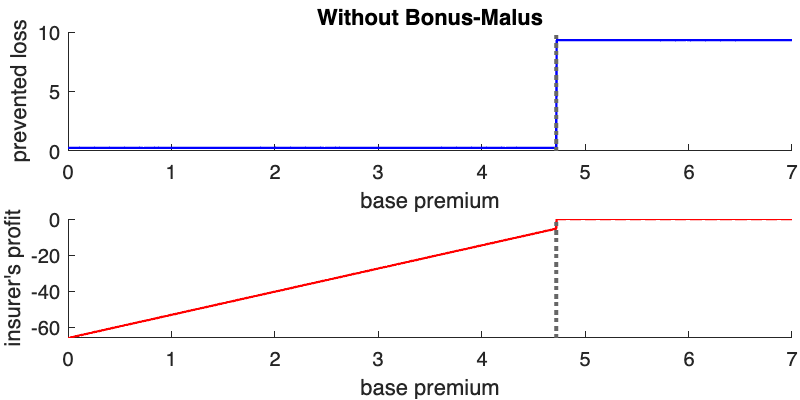


line_width = 1.2;

figure('Position', [100, 100, 400, 200]);
[ha, pos] = tight_subplot(2, 1, [0.17, 0.15], [0.155, 0.08], [0.085, 0.01]);

% upper panel
axes(ha(1));
hold on;
plot(premium_list, detail_list(:, 6), ...
    'LineWidth', line_width, 'Color', 'blue');
line([transition1, transition1], get(gca, 'YLim'), 'Color', [0.4, 0.4, 0.4], ...
    'LineStyle', ':', 'LineWidth', 2);

xlabel('base premium');
ylabel('prevented loss');

title("Without Bonus-Malus");

% lower panel
axes(ha(2));
hold on;
plot(premium_list, profit_list, ...
    'LineWidth', line_width, 'Color', 'red');
line([transition1, transition1], get(gca, 'YLim'), 'Color', [0.4, 0.4, 0.4], ...
    'LineStyle', ':', 'LineWidth', 2);

xlabel('base premium');
ylabel('insurer''s profit');

## Figure 2: retention of insurance customers and adoption of self-mitigation

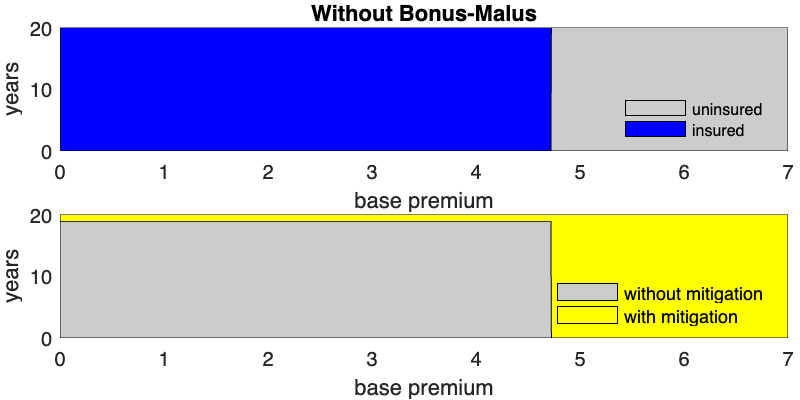

figure('Position', [100, 100, 400, 200]);
[ha, pos] = tight_subplot(2, 1, [0.16, 0.15], [0.155, 0.07], [0.075, 0.015]);

% upper panel
axes(ha(1));
BM_num = size(BM_retention_list, 2) - 1;
BM_legend = cell(BM_num + 1, 1);
BM_legend{1} = 'uninsured';
for BM_id = 1:BM_num
    BM_legend{BM_id + 1} = sprintf('insured');
end

colorlist = [[0.8, 0.8, 0.8]; winter];
colormap_rows = [1, round(linspace(2, 257, BM_num + 1))];

BM_list = [zeros(size(BM_retention_list, 1), 1), ...
    cumsum(BM_retention_list, 2)];
BM_list = min(BM_list, params.horizon);


hold on;
for BM_id = 1:BM_num + 1
    fill([premium_list; flipud(premium_list)], ...
        [BM_list(:, BM_id); flipud(BM_list(:, BM_id + 1))], ...
        colorlist(colormap_rows(BM_id), :), 'LineWidth', 0.5);
end
legend(BM_legend, 'Location', 'southeast', 'Orientation',"vertical", 'FontSize', 8, 'Color', 'none');
legend boxoff
xlabel('base premium');
ylabel('years')

title("Without Bonus-Malus");

% lower panel
axes(ha(2));
miti_legend = {'without mitigation', 'with mitigation'};

colorlist = [0.8, 0.8, 0.8; 1, 1, 0];

Miti_list = [zeros(size(Miti_retention_list, 1), 1), ...
    cumsum(Miti_retention_list, 2)];
Miti_list = min(Miti_list, params.horizon);

hold on;
for Miti_id = 1:length(Miti.cost)
    fill([premium_list; flipud(premium_list)], ...
        [Miti_list(:, Miti_id); flipud(Miti_list(:, Miti_id + 1))], ...
        colorlist(Miti_id, :), 'LineWidth', 0.5);
end
legend(miti_legend, 'Location', 'southeast', 'Orientation',"vertical", 'Color', 'none');
legend boxoff
xlabel('base premium');
ylabel('years')